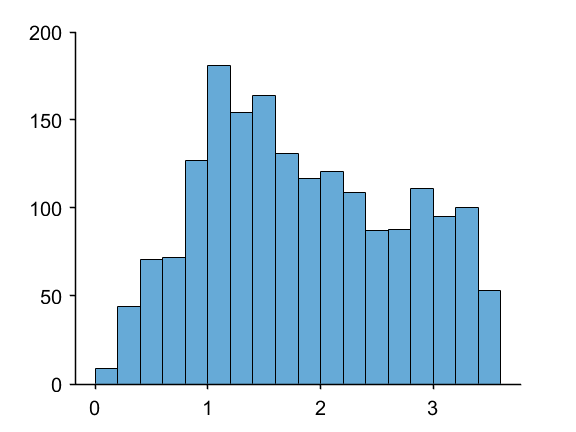

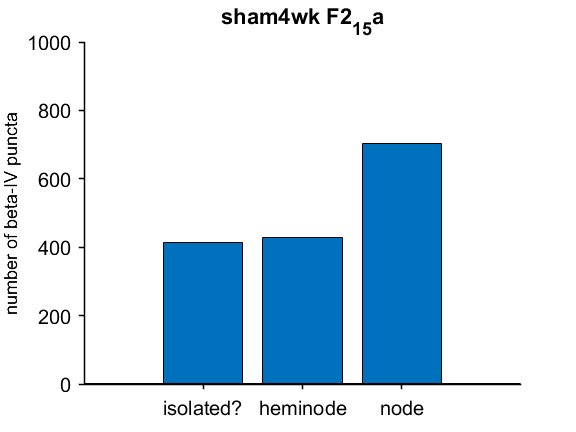

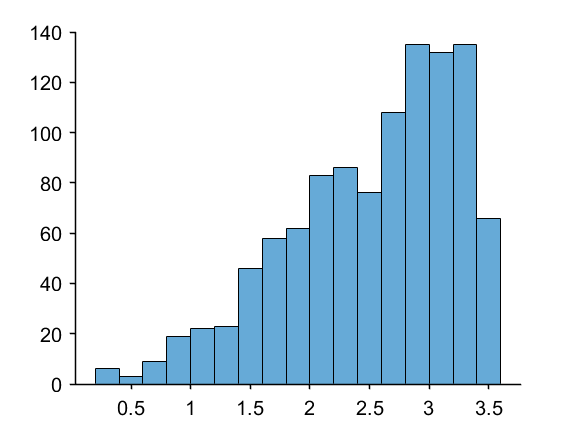

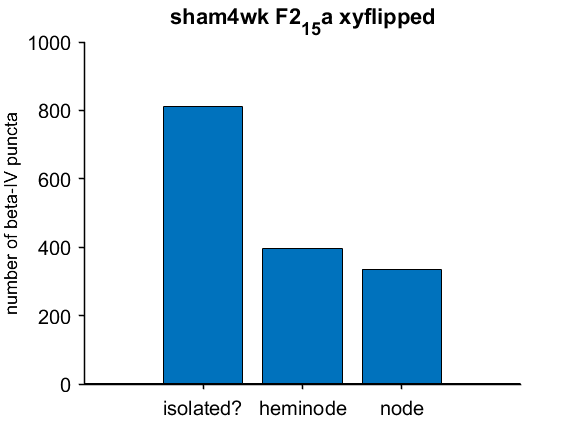

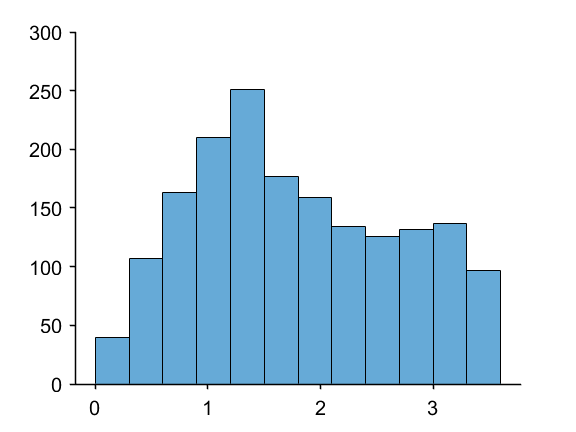

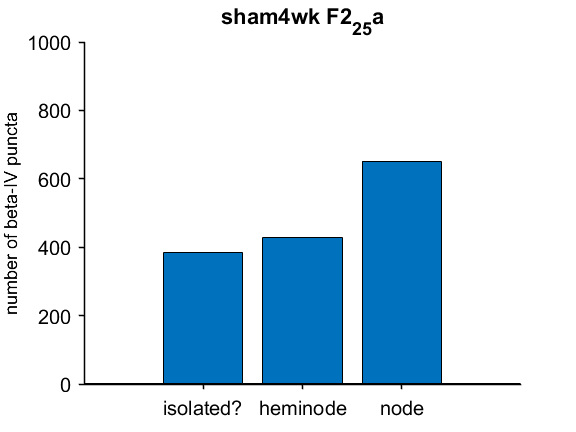

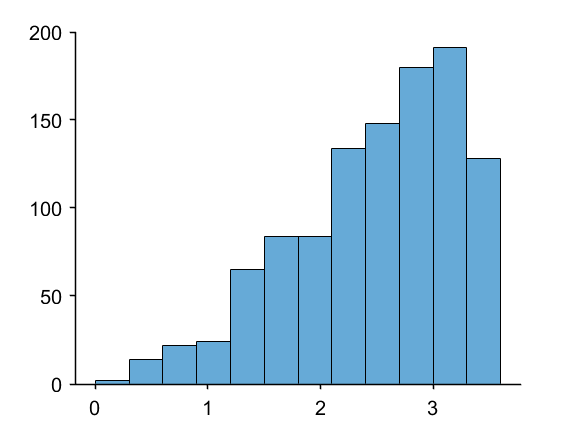

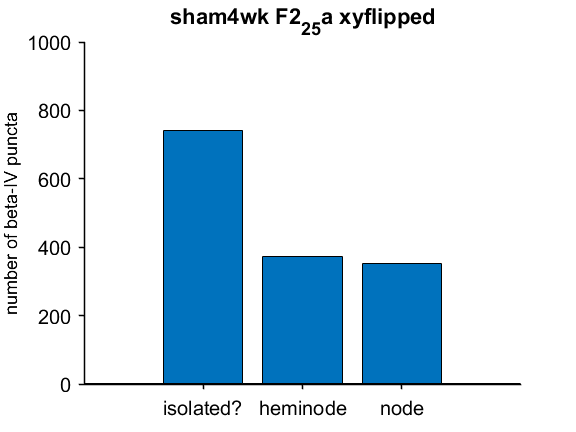

addpath(fullfile('.','FinalDataStructs'));
addpath(genpath(fullfile('.', 'MATLAB_code')));
maindir = fullfile('.','NodalComponents','Final_Imaris_Data');
addpath(genpath(maindir));
cd(maindir);
sham4wk_dir = dir(fullfile('.', 'sham4wk'));
sham6wk_dir = dir(fullfile('.', 'sham6wk'));
cupr4wk_dir = dir(fullfile('.', 'cupr4wk'));
cupr6wk_dir = dir(fullfile('.', 'cupr6wk'));
data = [];
data = parseNodeFolders(data, sham4wk_dir);

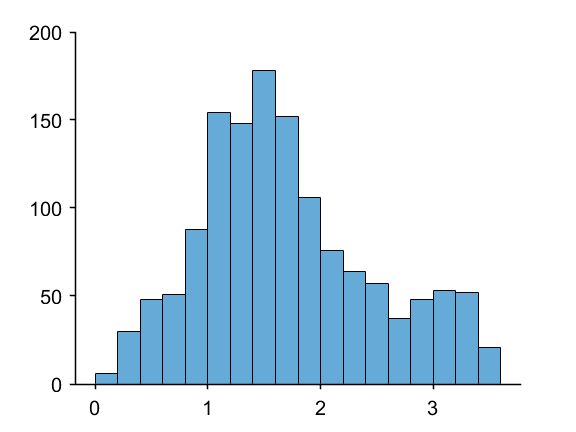

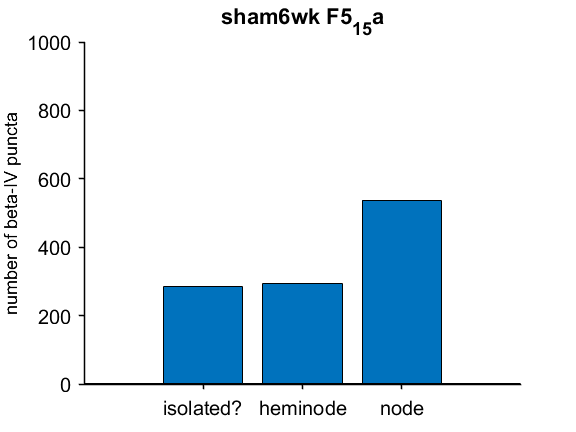

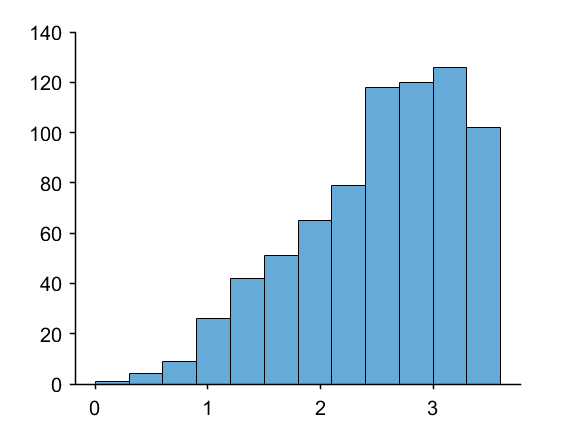

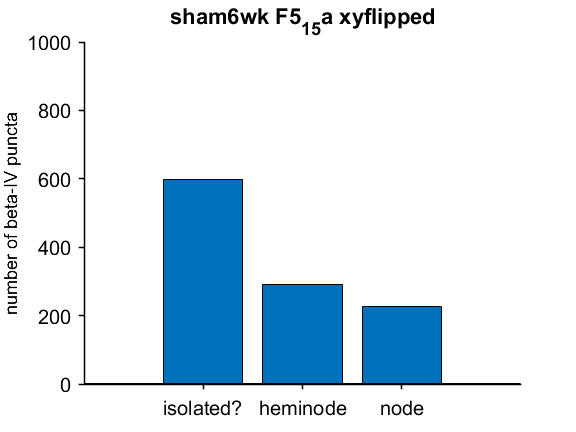

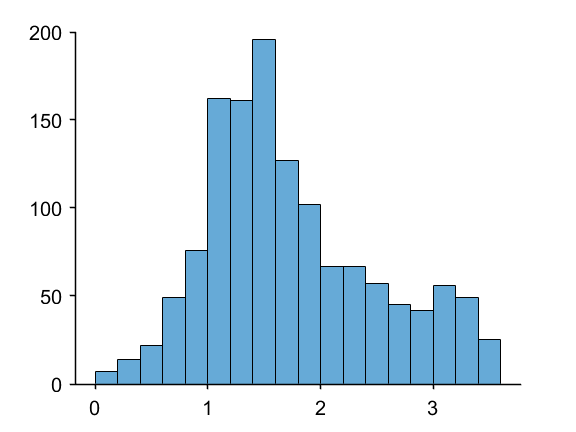

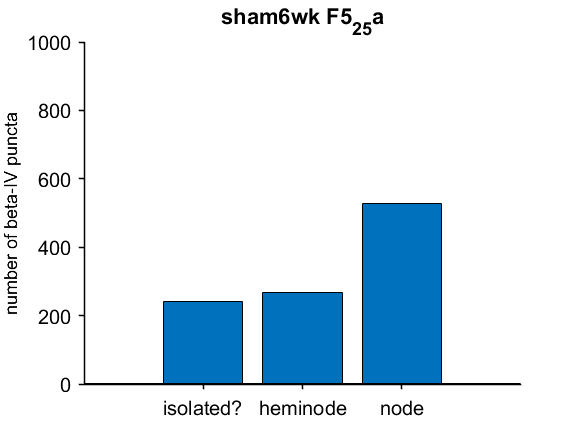

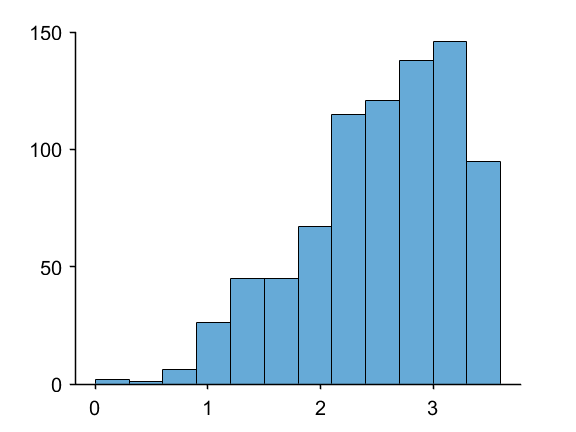

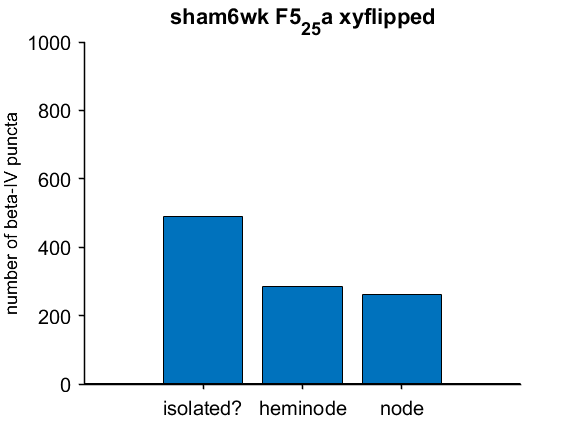

data = parseNodeFolders(data, sham6wk_dir);

data = parseNodeFolders(data, cupr4wk_dir);
data = parseNodeFolders(data, cupr6wk_dir);
cond = fieldnames(data);

## raw data graph

for c = 1:length(cond)
    an = fieldnames(data.(cond{c}));
    avg = [];
    for a = 1:length(an)
        avg = [avg; data.(cond{c}).(an{a}).avg];
    end
    data.(cond{c}).avg = mean(avg,1);
    data.(cond{c}).sem = calcSEM(avg,1);
end
allavg = [data.sham4wk.avg; data.sham6wk.avg; data.cupr4wk.avg; data.cupr6wk.avg];
allsem = [data.sham4wk.sem; data.sham6wk.sem; data.cupr4wk.sem; data.cupr6wk.sem];
figure
errorbarbar([1 2 3 4],allavg,allsem,{'stacked'},{'k.','MarkerSize',0.1});

ans =   1×3 Bar array:

    Bar    Bar    Bar


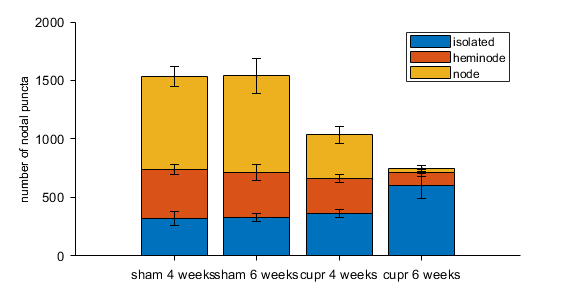

xticklabels({'sham 4 weeks' 'sham 6 weeks' 'cupr 4 weeks' 'cupr 6 weeks'})
legend({'isolated' 'heminode' 'node'})
ylabel('number of nodal puncta')
figQuality(gcf,gca,[6 3])

## proportion graph

for c = 1:length(cond)
    an = fieldnames(data.(cond{c}));
    avgP = [];
    for a = 1:length(an)-4
        avgP = [avgP; data.(cond{c}).(an{a}).avgP];
    end
    data.(cond{c}).avgP = mean(avgP,1);
    data.(cond{c}).semP = calcSEM(avgP,1);
end
allavgP = [data.sham4wk.avgP; data.sham6wk.avgP; data.cupr4wk.avgP; data.cupr6wk.avgP];
allsemP = [data.sham4wk.semP; data.sham6wk.semP; data.cupr4wk.semP; data.cupr6wk.semP];
figure
errorbarbar([1 2 3 4],allavgP,allsemP,{'stacked'},{'k.','MarkerSize',0.1});

ans =   1×3 Bar array:

    Bar    Bar    Bar


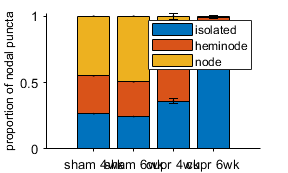

xticklabels({'sham 4wk' 'sham 6wk' 'cupr 4wk' 'cupr 6wk'})
legend({'isolated' 'heminode' 'node'})
ylabel('proportion of nodal puncta')
figQuality(gcf,gca,[3 1.8])